%% Perfect ideal fermi gas data
outp = IdealFermiGasDensity(-200:1.44:200);  
z_i = outp.z'; n_z = outp.n';  Pt = outp.Pt'; kt = outp.kt';


%% Method 1

% Universal Constants
uconst.h = 6.62607004e-34;
uconst.hbar = uconst.h / (2*pi);
uconst.massLi6 = 9.988346e-27;
% Experimental Constants, CHANGE ACCORDINGLY WITH THE EXPERIMENT
econst.trapw = 2*pi*23.9;

% Generate U_z
U_z = 0.5*uconst.massLi6*econst.trapw^2*z_i.^2;

% Sort in increasing U_z
[sU_z,sIndex] = sort(U_z);
sn_z = n_z(sIndex);
sz_i = z_i(sIndex);

% Dynamic binning
bU = zeros(size(sU_z));
bn = zeros(size(sU_z));
bz = zeros(size(sU_z));
dz = z_i(2) - z_i(1);
bindz = 0.5;

i=1; counter = 1; bi = 1;
while i<=length(sU_z)
    members = [i];
    j = i+1;
    while j<=length(sU_z) && (abs(sz_i(j))-abs(sz_i(i))) < (dz*bindz)
        members = [members, j]; j = j+1;
    end
    bU(bi) = mean(sU_z(members));
    bn(bi) = mean(sn_z(members));
    bz(bi) = mean(abs(sz_i(members)));
    i = j; bi = bi + 1;
end
bU = bU(1:bi-1);
bn = bn(1:bi-1);
bz = bz(1:bi-1);

% Calculate EF
bEF = real(uconst.hbar^2 / (2*uconst.massLi6) * (6*pi^2*bn).^(2/3));

% Calculate k/k0
diffsize = 1;
k = - diff(bEF) ./ diff(bU);
if diffsize ~= 0
    warning('off','MATLAB:polyfit:RepeatedPointsOrRescale');
    for i = 1:length(k)
        t = diffsize;
        p = polyfit(bU(max(1,i-t):min(length(bU),i+t)), bEF(max(1,i-t):min(length(bU),i+t)), 2);
        k(i) = - polyval(polyder(p),bU(i));
    end
end


% Calculate P/P0
P = zeros(size(bU));
% for i = 1:length(P)-1, for j = i:length(bU)-1, P(i) = P(i) + (bU(j+1)-bU(j))*bn(j); end; end
for i = 1:length(P)-1, P(i) = trapz(bU(i:end),bn(i:end)); end
% for i = 1:length(P)-1, P(i) = simps(bU(i:end),bn(i:end)); end
P = P(1:end-1); P = P ./ (2/5*bn(1:end-1).*bEF(1:end-1)) ;


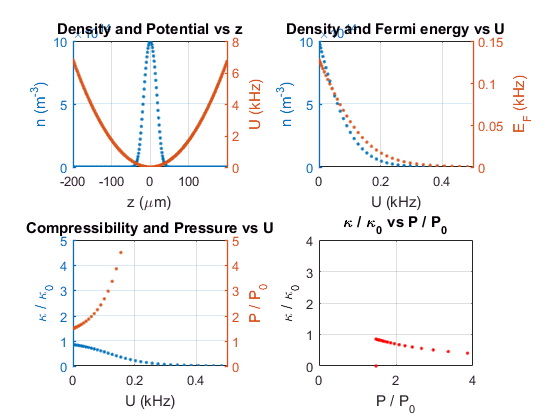

% plots
plot_maxU = 0.5;

figure;
subplot(2,2,1);
grid on; title('Density and Potential vs z');  xlim([z_i(1),z_i(end)]*1e6); xlabel('z (\mum)');
yyaxis left
plot(z_i*1e6,n_z,'.');  ylabel('n (m^{-3})');
yyaxis right
plot(z_i*1e6,U_z/(uconst.h*1e3),'.'); ylabel('U (kHz)');

subplot(2,2,2);
grid on;  title('Density and Fermi energy vs U'); xlabel('U (kHz)'); xlim([0,plot_maxU]); 
yyaxis left
plot(bU/(uconst.h*1e3),bn,'.');  ylabel('n (m^{-3})');
yyaxis right
plot(bU/(uconst.h*1e3),bEF/(uconst.h*1e3),'.');  ylabel('E_F (kHz)');

subplot(2,2,3);
grid on;  title('Compressibility and Pressure vs U');  xlabel('U (kHz)'); xlim([0,plot_maxU]);
yyaxis left
plot(bU(1:end-1)/(uconst.h*1e3),k,'.'); ylim([0 5]);  ylabel('\kappa / \kappa_0');
yyaxis right
plot(bU(1:end-1)/(uconst.h*1e3),P,'.'); ylim([0 5]); ylabel('P / P_0');

subplot(2,2,4);
plot(P,k,'r.'); xlim([0 4]); ylim([0 4]);
title('\kappa / \kappa_0 vs P / P_0'); xlabel('P / P_0'); ylabel('\kappa / \kappa_0'); grid on;

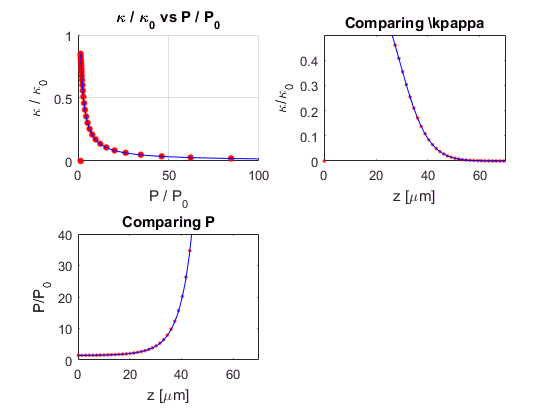

figure;
subplot(2,2,1);
hold on; plot(P,k,'r.','MarkerSize',15); plot(Pt,kt,'b-'); xlim([0 100]); ylim([0 1]); hold off;
title('\kappa / \kappa_0 vs P / P_0'); xlabel('P / P_0'); ylabel('\kappa / \kappa_0'); grid on;
subplot(2,2,2);
plot(bz(1:end-1)*1e6,k,'r.'); hold on; plot(z_i*1e6,kt,'b-'); hold off; title('Comparing \kpappa'); 
xlabel('z [\mum]'); xlim([0,70]); ylim([0 0.5]); ylabel('\kappa/\kappa_0');
subplot(2,2,3);
plot(bz(1:end-1)*1e6,P,'r.'); hold on; plot(z_i*1e6,Pt,'b-'); hold off; title('Comparing P');
xlabel('z [\mum]'); xlim([0,70]); ylim([0 40]); ylabel('P/P_0');

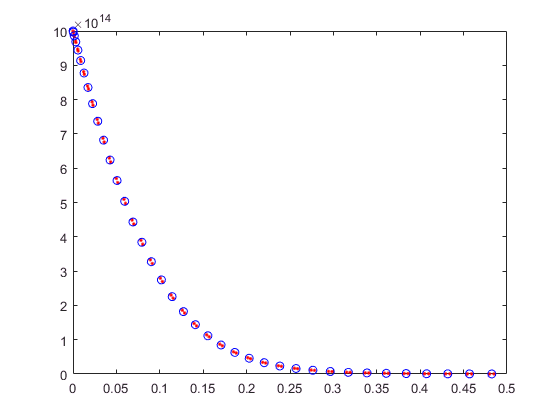


figure;
plot(sU_z/(uconst.h*1e3), sn_z, 'r.', bU/(uconst.h*1e3), bn, 'bo'); xlim([0 plot_maxU]);

% % dE = 0.01;
% % E0 = (0:dE:7)';
% % startstep = 0.05; 
% % 
% % allk = []; allP = [];
% % start = 0; counter = 0;
% % while start<dE
% %     [k,P] = EoS_nz_KvsP( z_i, n_z,'plot_maxU',6,'UkHz',(start:dE:7)','diffsize',3,'plot',0);
% %     allk = [allk;k]; allP = [allP;P]; start = start + startstep; counter = counter + 1;
% % end
% % figure; plot(allP,allk,'r.',Pt,kt,'b-'); xlim([0 30]); ylim([0 1]); title('EoS Ideal Fermi Gas');


% % %% Noisy data
% % averages = 10;
% % allk = []; allP = [];
% % for i = 1:averages
% %     PolarizedDataGenerator_Modified;
% %     dE = 0.02;
% %     E0 = (0:dE:7)';
% %     startstep = 0.002; 
% %     start = 0; counter = 0;
% %     while start<dE
% %         [k,P, U_i, EF_U, n_U, index1, index2 ] = EoS_nz_KvsP( y_vec, n_simulated_noise,'plot_maxU',6,'UkHz',(start:dE:7)','diffsize',0,'plot',0,'Urange',[0.01 1]);
% %         allk = [allk;k(index1:index2)]; allP = [allP;P(index1:index2)]; start = start + startstep; counter = counter + 1;
% %     end
% %     
% % end
% % figure; plot(allP,allk,'r.',PTilde,KappaTilde,'b-'); xlim([0 30]); ylim([0 1]); title('EoS Ideal Fermi Gas + Noise');